clear all;

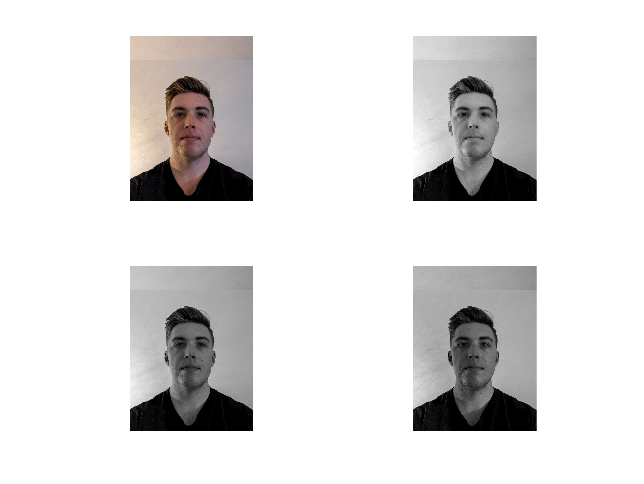

% Read the input image

% original_image = imread('city.jpg');
figure(1)
original_image = imread('me.jpg');
subplot(2,2,1)
imshow(original_image)
colormap(gray);

imageSize = size(original_image);

one_image = original_image(:,:,1);
% rgb2gray(original_image);
subplot(2,2,2)
imshow(one_image)
two_image = original_image(:,:,2);
subplot(2,2,3)
imshow(two_image)
three_image = original_image(:,:,3);
subplot(2,2,4)
imshow(three_image)

% denoise

denoise_image = wdenoise2(one_image);

% imshow(denoise_image);

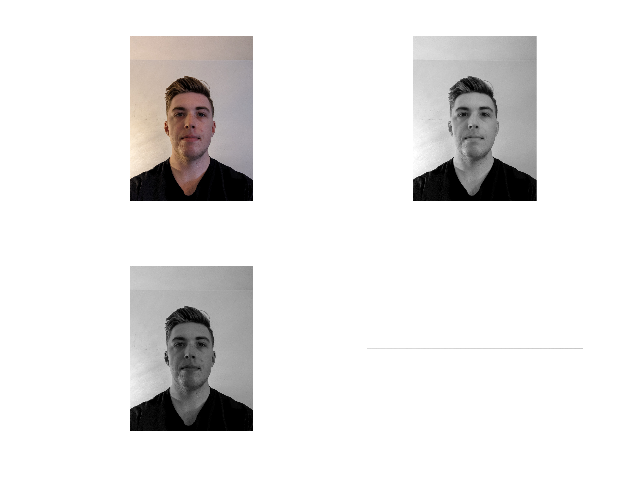

% display some wavelet

[phi1,psi1,xval1] = wavefun('db8',10);
[phi2,psi2,xval2] = wavefun('haar',10);
[phi3,psi3,xval3] = wavefun('sym4',10); 
[phi4,psi4,xval4] = wavefun('bior4.4',10); % good for denoise, default
[psi5,xval5] = wavefun('gaus8',10); 

ylim([-2, 2]);

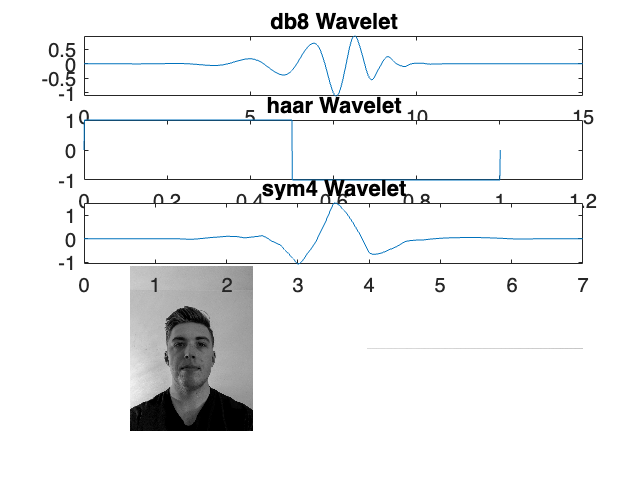

subplot(5, 1, 1);
plot(xval1,psi1);
title('db8 Wavelet');
subplot(5, 1, 2);
plot(xval2,psi2);
title('haar Wavelet');
subplot(5, 1, 3);
plot(xval3,psi3);
title('sym4 Wavelet');

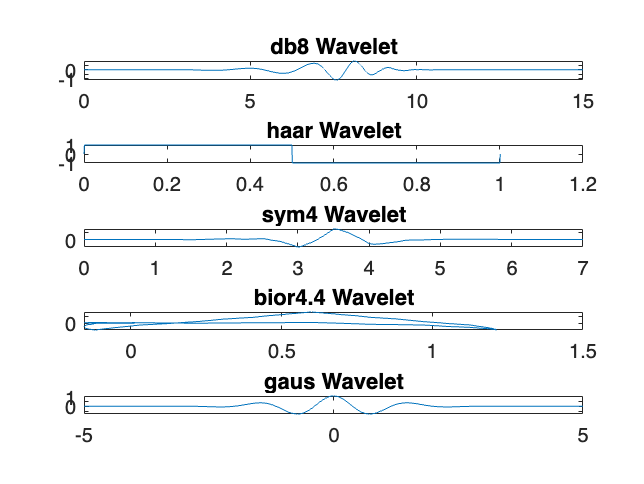

subplot(5, 1, 4);
plot(xval4,psi4);
title('bior4.4 Wavelet'); 
subplot(5, 1, 5);
plot(xval5,psi5);
title('gaus Wavelet');

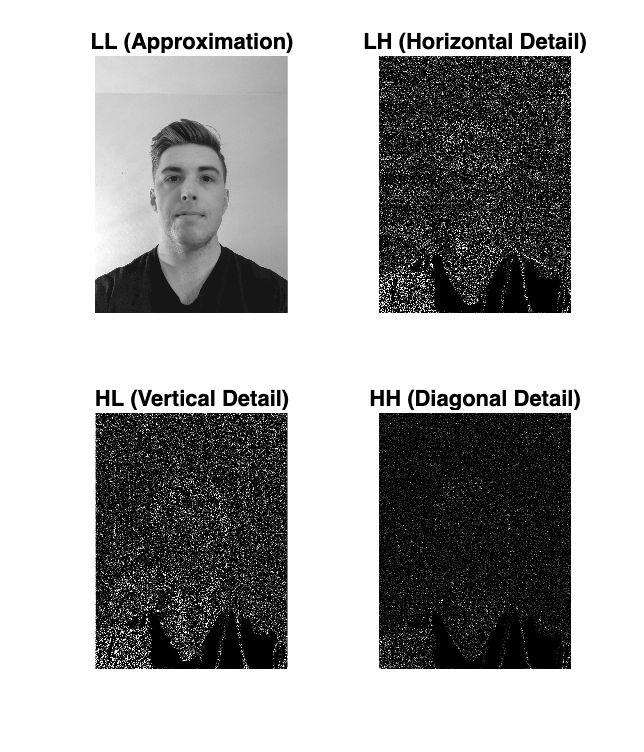

% choose the wavelet
wavelet = 'db4'; % 'db8', 'sym8', 'haar'

% Perform wavelet decomposition
[LL, LH, HL, HH] = dwt2(double(one_image), wavelet, 'mode', 'per');
% dwt2(X,'sym4','mode','per');

% Display the wavelet coefficients
figure(2);
subplot(2, 2, 1);
imshow(LL, []);
title('LL (Approximation)');
subplot(2, 2, 2);
imshow(LH, [0 3], "InitialMagnification", 'fit');
title('LH (Horizontal Detail)');
subplot(2, 2, 3);
imshow(HL, [0 3], "InitialMagnification", 'fit');
title('HL (Vertical Detail)');
subplot(2, 2, 4);
imshow(HH,[0 3], "InitialMagnification", 'fit');
title('HH (Diagonal Detail)');

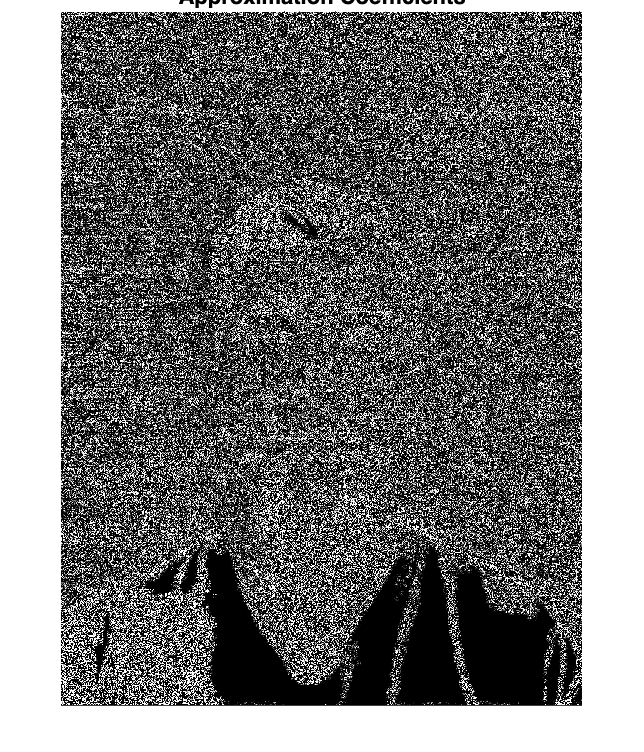

figure()
imshow(LH)
title('Approximation Coefficients')

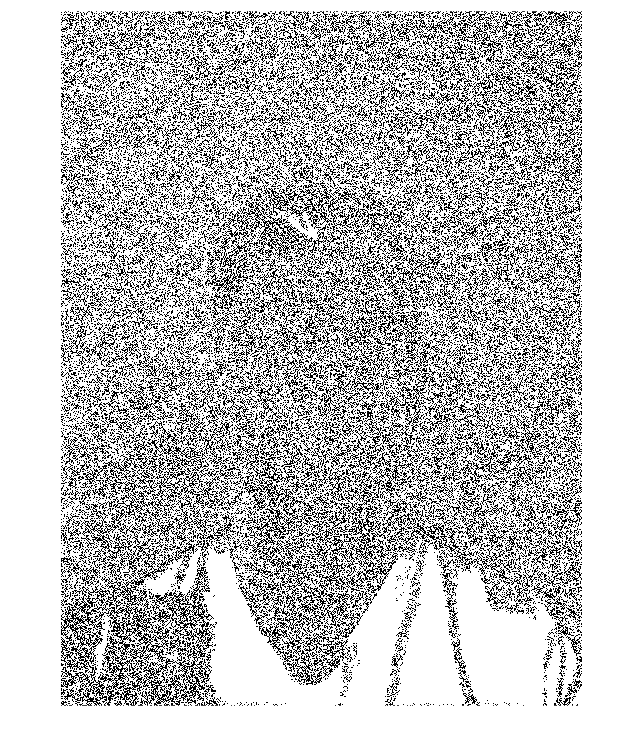

line_image = zeros(size(HH));

for i = 1:size(HH, 1)
    for j = 1:size(HH, 2)
        if HH(i, j) > 0
            line_image(i, j) = 0;
        else
            line_image(i, j) = 255;
        end
    end
end

imshow(line_image, [])
title(' ')

% https://en.wikipedia.org/wiki/Discrete_wavelet_transform

% canny edge detection
